# Lab #1: Halftoning

Author: Alejandro Sanchez

Date: February 13, 2022

## Abstract

The goal of this lab is to transform a grayscale image into a halftone image. This MATLAB script includes a halftone function that creates matrices containing black and white pixels and uses them to replace pixels in a grayscale image whose pixel values vary. This method outputs an image that appears very similar to to the input grayscale image, but only uses black and white pixels. This report will discuss the techniques used to successfully create halftone transformations and what each output image tells us about the performance of program.

## Technical Discussion

The program starts by reading an image using the `imread()` function. The images that are used in this lab include "`Fig0225(a)(face).tif`", "`Fig0225(b)(cameraman).tif`", and "`Fig0225(c)(crowd).tif`". The image files are converted to the `uint8` type and assigned to a matrix.

inputMatrixA = im2uint8(imread("Fig0225(a)(face).tif"));
inputMatrixB = im2uint8(imread("Fig0225(b)(cameraman).tif"));
inputMatrixC = im2uint8(imread("Fig0225(c)(crowd).tif"));

After the images are converted to type `uint8`, they are sent to the the `Halftone` function as arguments. The result of the `Halftone` function is assigned to a matrix as `logical` type as binary representations of the halftone transformation.

outputMatrixA = Halftone(inputMatrixA);
outputMatrixB = Halftone(inputMatrixB);
outputMatrixC = Halftone(inputMatrixC);

The Halftone function is designed to have a matrix input as 

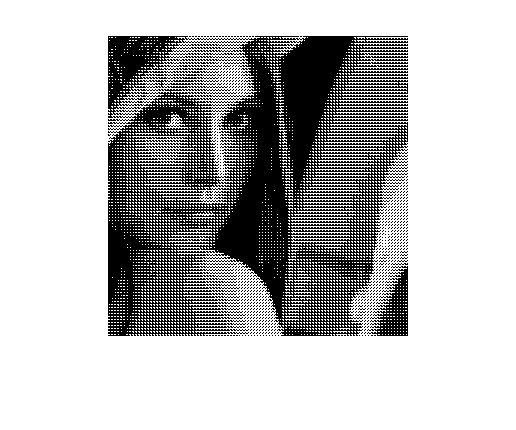

figure()
imshow(outputMatrixA);

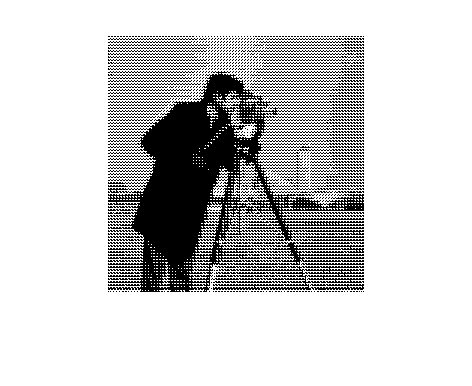


figure()
imshow(outputMatrixB);

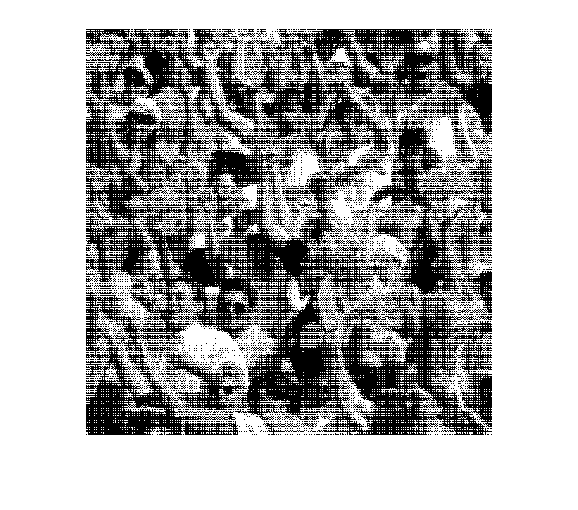


figure()
imshow(outputMatrixC);

function output = Halftone(inputImage)
    A = inputImage;
    % Number of pixel rows and columns in the image
    rows = size(A,1);
    cols = size(A,2);

    %Detecting if image is not divisible by 3 evenly
    r_remain = rem(rows, 3);
    c_remain = rem(cols, 3);

    % Creating halftone transform matrices
    dot9 = [0 0 0; 0 0 0; 0 0 0];
    dot8 = [0 0 0; 0 255 0; 0 0 0];
    dot7 = [0 0 0; 255 255 0; 0 0 0];
    dot6 = [0 0 0; 255 255 0; 0 255 0];
    dot5 = [0 0 0; 255 255 255; 0 255 0];
    dot4 = [0 0 255; 255 255 255; 0 255 0];
    dot3 = [0 0 255; 255 255 255; 255 255 0];
    dot2 = [255 0 255; 255 255 255; 255 255 0];
    dot1 = [255 0 255; 255 255 255; 255 255 255];
    dot0 = [255 255 255; 255 255 255; 255 255 255];
    
    f = waitbar(0, "Processing");

    right_edge_catch = false;
    % LEFT-RIGHT TRANSFORM
    for row_idx = 1:3:rows
        waitbar(row_idx/rows,f,sprintf("Processing %.f%%", (row_idx/rows)*100));
        pause(0);
        right_edge_corrected = false;
        for col_idx = 1:3:cols
            if (right_edge_catch == false && col_idx+2<=cols && row_idx+2<=rows)
                % Normal preparation for transform
                PXL_AVG = round(mean(A(row_idx:row_idx+2,col_idx:col_idx+2), "all"));
               
                if (PXL_AVG>0 && PXL_AVG<=25)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot9;
                   
                elseif (PXL_AVG>=26 && PXL_AVG<=51)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot8;
                   
                elseif (PXL_AVG>=52 && PXL_AVG<=77)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot7;
                   
                elseif (PXL_AVG>=78 && PXL_AVG<=103)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot6;
                   
                elseif (PXL_AVG>=104 && PXL_AVG<=129)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot5;
                   
                elseif (PXL_AVG>=130 && PXL_AVG<=155)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot4;
                   
                elseif (PXL_AVG>=156 && PXL_AVG<=181)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot3;
                   
                elseif (PXL_AVG>=182 && PXL_AVG<=207)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot2;
                   
                elseif (PXL_AVG>=208 && PXL_AVG<=233)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot1;
                   
                elseif (PXL_AVG>=234 && PXL_AVG<=255)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot0;
                   
                end
            % RIGHT EDGE TRANSFORM
            elseif (row_idx+2<=rows)
                right_edge_catch = false;
                right_edge_corrected = true;
                PXL_AVG = round(mean(A(row_idx:row_idx+2,col_idx:col_idx+c_remain-1), "all"));
               
                if (PXL_AVG>0 && PXL_AVG<=25)
                    A(row_idx:row_idx+2,col_idx:col_idx+c_remain-1) = dot9(:,1:c_remain);
                   
                elseif (PXL_AVG>=26 && PXL_AVG<=51)
                    A(row_idx:row_idx+2,col_idx:col_idx+c_remain-1) = dot8(:,1:c_remain);
                   
                elseif (PXL_AVG>=52 && PXL_AVG<=77)
                    A(row_idx:row_idx+2,col_idx:col_idx+c_remain-1) = dot7(:,1:c_remain);
                   
                elseif (PXL_AVG>=78 && PXL_AVG<=103)
                    A(row_idx:row_idx+2,col_idx:col_idx+c_remain-1) = dot6(:,1:c_remain);
                   
                elseif (PXL_AVG>=104 && PXL_AVG<=129)
                    A(row_idx:row_idx+2,col_idx:col_idx+c_remain-1) = dot5(:,1:c_remain);
                   
                elseif (PXL_AVG>=130 && PXL_AVG<=155)
                    A(row_idx:row_idx+2,col_idx:col_idx+c_remain-1) = dot4(:,1:c_remain);
                   
                elseif (PXL_AVG>=156 && PXL_AVG<=181)
                    A(row_idx:row_idx+2,col_idx:col_idx+c_remain-1) = dot3(:,1:c_remain);
                   
                elseif (PXL_AVG>=182 && PXL_AVG<=207)
                    A(row_idx:row_idx+2,col_idx:col_idx+c_remain-1) = dot2(:,1:c_remain);
                   
                elseif (PXL_AVG>=208 && PXL_AVG<=233)
                    A(row_idx:row_idx+2,col_idx:col_idx+c_remain-1) = dot1(:,1:c_remain);
                   
                elseif (PXL_AVG>=234 && PXL_AVG<=255)
                    A(row_idx:row_idx+2,col_idx:col_idx+c_remain-1) = dot0(:,1:c_remain);
                   
                end
            end
            
            %%
            if (col_idx+3>=cols)
                if (c_remain > 0 && right_edge_corrected == false)
                    right_edge_catch = true;
                else
                    break;
                end
            end
        end
        if (row_idx+3>=rows)
            break;
        end
    end

    % BOTTOM EDGE TRANSFORM
    if (r_remain > 0)
        row_idx = rows-2;
        for col_idx = 1:3:cols
            if (col_idx+2<=cols)
                PXL_AVG = round(mean(A(row_idx:row_idx+2,col_idx:col_idx+2), "all"));
               
                if (PXL_AVG>0 && PXL_AVG<=25)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot9;
                   
                elseif (PXL_AVG>=26 && PXL_AVG<=51)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot8;
                   
                elseif (PXL_AVG>=52 && PXL_AVG<=77)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot7;
                   
                elseif (PXL_AVG>=78 && PXL_AVG<=103)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot6;
                   
                elseif (PXL_AVG>=104 && PXL_AVG<=129)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot5;
                   
                elseif (PXL_AVG>=130 && PXL_AVG<=155)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot4;
                   
                elseif (PXL_AVG>=156 && PXL_AVG<=181)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot3;
                   
                elseif (PXL_AVG>=182 && PXL_AVG<=207)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot2;
                   
                elseif (PXL_AVG>=208 && PXL_AVG<=233)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot1;
                   
                elseif (PXL_AVG>=234 && PXL_AVG<=255)
                    A(row_idx:row_idx+2,col_idx:col_idx+2) = dot0;
                   
                end
            % BOTTOM-RIGHT CORNER TRANSFORM
            else
                PXL_AVG = round(mean(A(rows-2:rows,cols-2:cols), "all"));
               
                if (PXL_AVG>0 && PXL_AVG<=25)
                    A(rows-2:rows,cols-2:cols) = dot9;
                   
                elseif (PXL_AVG>=26 && PXL_AVG<=51)
                    A(rows-2:rows,cols-2:cols) = dot8;
                   
                elseif (PXL_AVG>=52 && PXL_AVG<=77)
                    A(rows-2:rows,cols-2:cols) = dot7;
                   
                elseif (PXL_AVG>=78 && PXL_AVG<=103)
                    A(rows-2:rows,cols-2:cols) = dot6;
                   
                elseif (PXL_AVG>=104 && PXL_AVG<=129)
                    A(rows-2:rows,cols-2:cols) = dot5;
                   
                elseif (PXL_AVG>=130 && PXL_AVG<=155)
                    A(rows-2:rows,cols-2:cols) = dot4;
                   
                elseif (PXL_AVG>=156 && PXL_AVG<=181)
                    A(rows-2:rows,cols-2:cols) = dot3;
                   
                elseif (PXL_AVG>=182 && PXL_AVG<=207)
                    A(rows-2:rows,cols-2:cols) = dot2;
                   
                elseif (PXL_AVG>=208 && PXL_AVG<=233)
                    A(rows-2:rows,cols-2:cols) = dot1;
                   
                elseif (PXL_AVG>=234 && PXL_AVG<=255)
                    A(rows-2:rows,cols-2:cols) = dot0;
                   
                end
            end
        end
    end
    delete(f)
    output = imbinarize(A);
end

## Results